#  Cvičení 1 - Bonus - B2M31AEDA

## 1) Fibonacciho posloupnost

Fibonacciho posloupnost vypadá následovně:


$$\begin{array}{l}
F=0,1,1,2,3,5,\ldots\;\\
F_0 =0,F_1 =1,F_n =F_{n-1} +F_{n-2} \;,\ldots
\end{array}$$


Napište funkci, která bude brát jediný, libovolný, kladný, celočíselný vstup `N`, a bude generovat na výstupu příslušnou `N`-tou hodnotu Fibonacciho posloupnosti.

% function Fn = myFibonacci(N)
%     if ~isnumeric(N)
%         error("Invalid input: Not a number!")
%     elseif N < 2
%         if N < 0
%             error("Invalid input: Negative number!")
%         else
%             Fn = N;
%         end
%     else
%         Fn_2 = 0;
%         Fn_1 = 1;
%         for n = 2:N
%             Fn = Fn_1 + Fn_2;
%             Fn_2 = Fn_1;
%             Fn_1 = Fn;
%         end
%     end
% end

Vydělením dvou sousedících prvků Fibonacciho posloupnosti pro N >> 1 (např. 1000), vám vyjde přibližná hodnota Zlatého řezu phi.


$$\hat{\mathrm{𝜑}} =\frac{F_N }{F_{N-1} };N>1$$


Čím větší bude `N`, tím bude hodnota blíže skutečné hodnotě phi. Ilustrujte pomocí grafu, jak se výpočet zlatého řezu pomocí Fibonacciho čísel blíží jeho skutečné hodnotě. Vyneste do grafu hodnoty aproximací pro tolik `N`, kolik uznáte za vhodné (dokud se hodnota dostatečně nepřiblíží) a konstantní čáru reprezentující skutečnou hodnotu. Nezapomeňte popsat osy, aktivovat mřížku, dodat legendu atd.

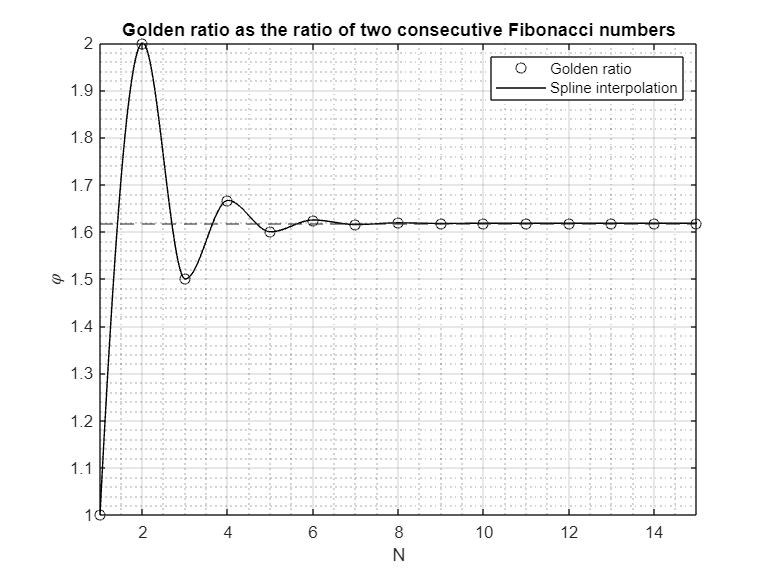

N = 16;
nRange = 1:N-1;
goldenRatio = zeros(1,N-1);
for n = nRange
    goldenRatio(n) = myFibonacci(n+1)/myFibonacci(n);
end
fineRange = 1:1e-2:N-1;
interpolation = pchip(nRange, goldenRatio, fineRange);

figure("Name", "Golden ratio")
plot(nRange, goldenRatio, 'o', 'Color', 'k')
hold on
plot(fineRange, interpolation, '-', 'Color', 'k')
yline((1+sqrt(5))/2, '--')
axis tight
grid on
grid minor
xlabel("N")
ylabel({'$\varphi$'},'Interpreter','latex')
legend("Golden ratio", "Spline interpolation")
title("Golden ratio as the ratio of two consecutive Fibonacci numbers")
hold off

#### Otázky:

- Slovy napište minimálně 3 případy, kde se Fibonacciho posloupnost vyskytuje v přírodě.

- Logaritmické spirály: Mnohé objekty tvaru spirály, na které člověk v přírodě narazí (např. šnečí ulita nebo galaxie), jsou logaritmickými spirálami, jejichž faktorem růstu je zlatý řez.

- Hudba: Napříč historií hudby různí renesanční i post-renesanční skladatelé komponovali hudbu po vzoru Fibonacciho posloupnosti, což mělo často za výsledek (pro lidské ucho) melodicky příjemné a harmonické sekvence.

- Botanická uspořádání: Mnoho rostlin vykazují podobnost uspořádání s Fibonacciho posloupností. Toto uspořádání může být například rozložení listů na stonku, tvar šišek či semen v květu.

- Populace zvířat: Jako jeden z nejstarších a nejznámnějších výskytů Fibonacciho posloupnosti se s ní můžeme setkat jako s rychlostí růstu populace některých druhů zvěře (originálně králíků) ve specificky ideálních podmínkách pro rozmnožování.

## 2) Pascalova matice

Napište funkci, která bude generovat Pascalovu matici. Funkce bude mít jeden celočíselný, kladný vstup `N`, a na výstupu bude generovat matici `P` o velikosti `N×N`, která bude symetrická a bude obsahovat hodnoty binomiálních koeficientů (více info v návodu ke cvičení).

Matice bude iniciovaná jako matice jedniček, a dále se budou hodnoty matice vypočítávat tak, aby každý prvek byl dán součtem prvků které jsou o jeden řádek výše a jeden sloupec vlevo:


$$P\left(i,j\right)=P\left(i-1,j\right)+P\left(i,j-1\right)\;;1\le i,j\le N$$


% function P = myPascal(N)
%     if ~isnumeric(N)
%         error("Invalid input: Not a number!")
%     elseif N < 0
%         error("Invalid input: Negative number!")
%     else
%         P = ones(N);
%         for i = 2:N
%             for j = 2:N
%                 P(i,j) = P(i-1,j) + P(i,j-1);
%             end
%         end
%     end
% end

disp(myPascal(10))

           1           1           1           1           1           1           1           1           1           1
           1           2           3           4           5           6           7           8           9          10
           1           3           6          10          15          21          28          36          45          55
           1           4          10          20          35          56          84         120         165         220
           1           5          15          35          70         126         210         330         495         715
           1           6          21          56         126         252         462         792        1287        2002
           1           7          28          84         210         462         924        1716        3003        5005
           1           8          36         120         330         792        1716        3432        6435       11440
           1           9        

#### Otázky:

- Slovy odpovězte, jakým způsobem byste mohli z Pascalovy matice získat čísla Fibonacciho posloupnosti.

Z n-tého řádku Pascalovy matice, resp. Pascalova trojůhelníku, lze získat n-tý člen Fibonacciho posloupnosti jako součet prvků při diagonálním průchodu Pascalova trojúhelníku počínaje prvkem 1 na oné (n-té) řádce směrem nahoru. Platí tedy


$$F_n =\sum_{k,1+k\le n-k} P_{n-k,1+k}$$


tj. dokud druhý index $1+k$ nepřesahne počet prvků v řádku trojúhelníka.

## 3) Mandelbrotova množina

Pomocí návodu si naprogramujte výpočet Mandelbrotovy množiny a zobrazte si jí. Postup naleznete v návodu ke cvičení.

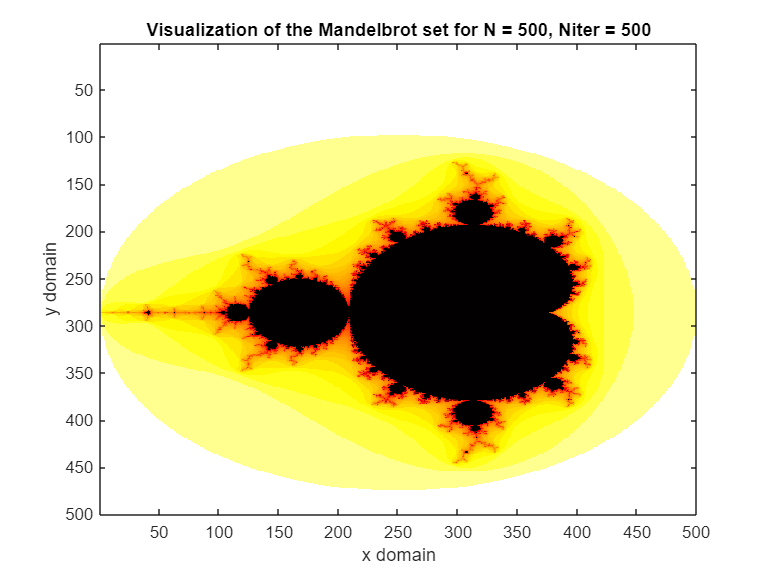

N = 500;
Niter = 500;
x = repmat(linspace(-2, 1, N), N, 1);
y = repmat(linspace(-2, 1.5, N)', 1, N);
z0 = x + 1i*y;
mandelbrot = ones(N);
z = z0;
for n = 1:Niter
    z = z.*z + z0;
    for i = 1:N
        for j = 1:N
            if abs(z(i,j)) < 2
                mandelbrot(i,j) = mandelbrot(i,j) + 1;
            end
        end
    end
end
mandelbrot = log(mandelbrot);

figure("Name", "Mandelbrot set visualization")
imagesc(mandelbrot)
xlabel("x domain")
ylabel("y domain")
title(['Visualization of the Mandelbrot set for N = ' num2str(N) ', Niter = ' num2str(Niter)])

colormap(flipud(hot))